mbqvalid = minibatchqueue(augimdsValidation,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["SSCB" ""]);
predictions = [];
while hasdata(mbqvalid)
% Read mini-batch of data.
    dlX = next(mbqvalid);
  
    % Make predictions using the predict function.
    dlYPred = predict(net,dlX);

    % Determine corresponding classes.
    predBatch = onehotdecode(dlYPred,labels,1);
    predictions = [predictions predBatch];
end

Visualize some of the predictions.

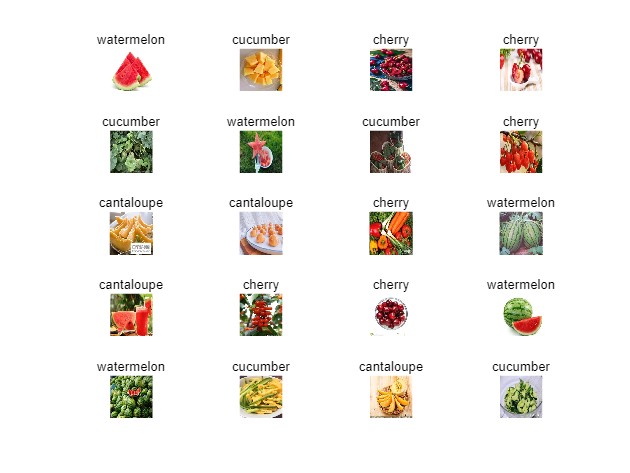

numObservations = numel(imdsValidation.Files);
idx = randperm(numObservations,20);
figure(2)
for i = 1:20
    subplot(5,4,i)
    I = imread(imdsValidation.Files{idx(i)});    
    label = predictions(idx(i));
    imshow(I)
    title(string(label))
  
end